# A von Karman plate with 1:1 internal resonance

In this example, we consider the same problem as that of vonKarmanPlateBook but with higher fidelty of discretization. Specifically, the plate is discretized with 20,000 elements and then 60,006 degrees-of-freedom. The dimension of the phase space of the full system is then 120,012. We use parallel computation of SSM such that the forced response curve of such a high-dimensional system can be obtained in 20 minutes.

## Geometry and finite element model

Building FE model


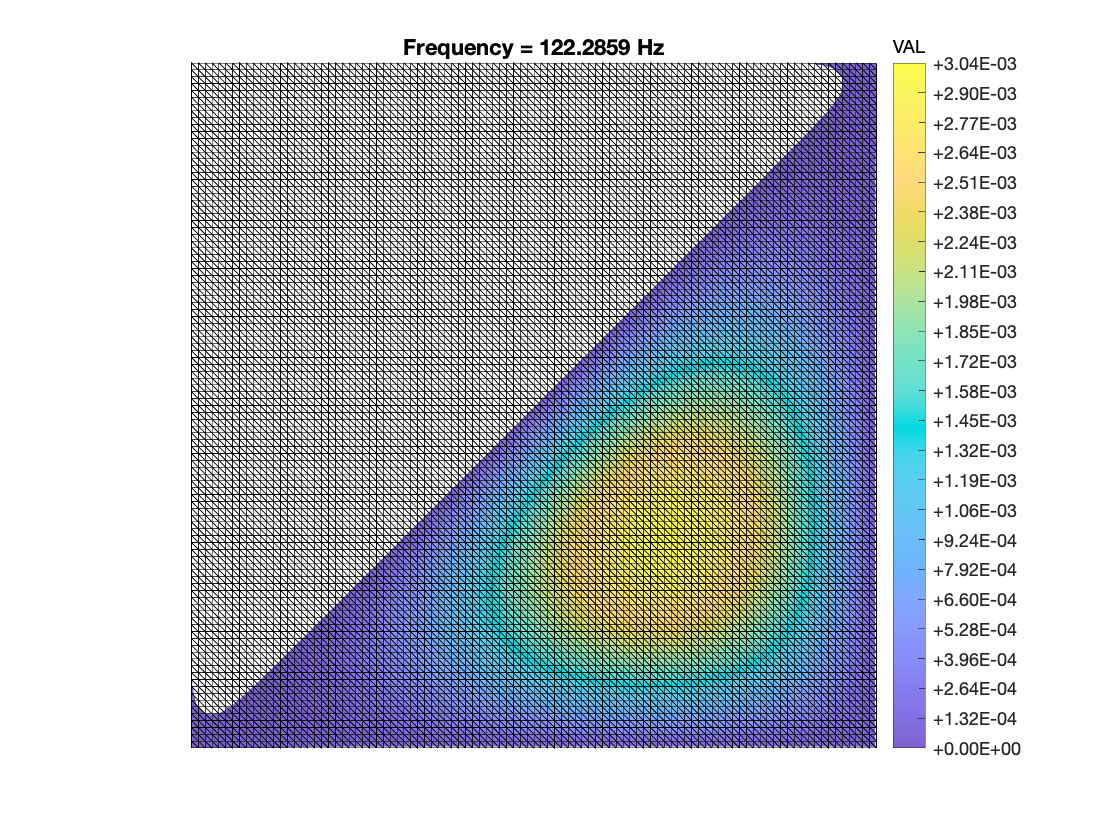

Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem
The circular natural frequencies of the first five modes:


omega = 	1.0e+03 *

    0.3074
    0.7683
    0.7684
    1.2293
    1.5367


Using Rayleigh damping
Getting nonlinearity coefficients
Loaded tensors from storage
Assembling external force vector


clear all
% Geometry
a = 1; % length of domain [m]
b = 1;  % breadth of domain [m]
t = 1e-2; % thickness of plate [m]
w = 0.0; % curvature parameter (height of the midpoint relative to ends) [m]
% material properties
E     = 70e9;  % 70e9 % 200e9 % Young's modulus [Pa]
rho   = 2700; % 2700 % 7850 % density [kg/m^3]
nu    = 0.33;    % Poisson's ratio 
kappa = 1e5; % material damping modulus 1e8

% Mesh
nElements = 100;
na = nElements;  
nb = nElements;
bc = 'SSSS';
startFE = tic;
[M,C,K,fnl,~,outdof] = build_model(a,b,t,w,E,rho,nu,kappa,bc,na,nb);

timeFE = toc(startFE);


## Dynamical System Setup

DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',3,'Nmax',10,'notation','multiindex')

## **Linear Modal analysis**

[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 3 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.241509e-03
modal damping ratio for 2 mode is 2.187439e-03
modal damping ratio for 3 mode is 2.187485e-03
the left eigenvectors may be incorrect in case of asymmetry of matrices

 The first 6 eigenvalues are given as 
   1.0e+02 *

  -0.0069 + 3.0735i
  -0.0069 - 3.0735i
  -0.0168 + 7.6834i
  -0.0168 - 7.6834i
  -0.0168 + 7.6838i
  -0.0168 - 7.6838i



## Add forcing

n = length(M);
f_0 = zeros(n,1);
f_0(outdof(1)) = 100;
epsilon = 0.5; % good
kappas = [1; -1];
coeffs = epsilon * [f_0 f_0]/2;
DS.add_forcing(coeffs, kappas);

## SSM Computation

**Activate parallel computation with the number of cores **

S = SSM(DS);
numWorkers = 8;
S.activate_parallel(numWorkers);                   % 8 workers for parallel computing

----------------------------------------------------------------
Starting parallel pool for the first time and detecting number
of available cores.
----------------------------------------------------------------
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).


set(S.FRCOptions, 'nonAutoParRedCom',true);        % Reduce communication on

**Extract FRC**

setup options

set(S.Options, 'reltol', 0.8,'notation','multiindex','IRtol',0.002)
set(S.FRCOptions, 'method','continuation ep') 
set(S.FRCOptions, 'SampStyle','cocoBD');                       % sampling style
set(S.FRCOptions, 'initialSolver', 'fsolve');   % solver for initial solution
set(S.contOptions, 'h_min',1e-4,'h_max',5, 'PtMX',2000);              % continuation setting
set(S.FRCOptions, 'outdof',outdof)

choose frequency range around the first natural frequency

freqRange  = [0.95 1.1]*imag(D(3));

extract forced response curve

order = 5;
FRC = S.extract_FRC('freq',freqRange,order);

The master subspace has internal resonances: [1  1  1  1]
*****************************************
Calculating FRC using SSM with master subspace: [3  4  5  6]
sigma_out = 0
sigma_in = 1
Manifold computation time at order 2 = 00:00:12
Estimated memory usage at order  2 = 3.69E+02 MB
Manifold computation time at order 3 = 00:00:42
Estimated memory usage at order  3 = 6.95E+02 MB
Manifold computation time at order 4 = 00:03:52
Estimated memory usage at order  4 = 9.76E+02 MB
Manifold computation time at order 5 = 00:12:47
Estimated memory usage at order  5 = 2.06E+03 MB

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradie

Total time spent on FRC computation upto O(5) = 00:23:24


deactivate parallel computing

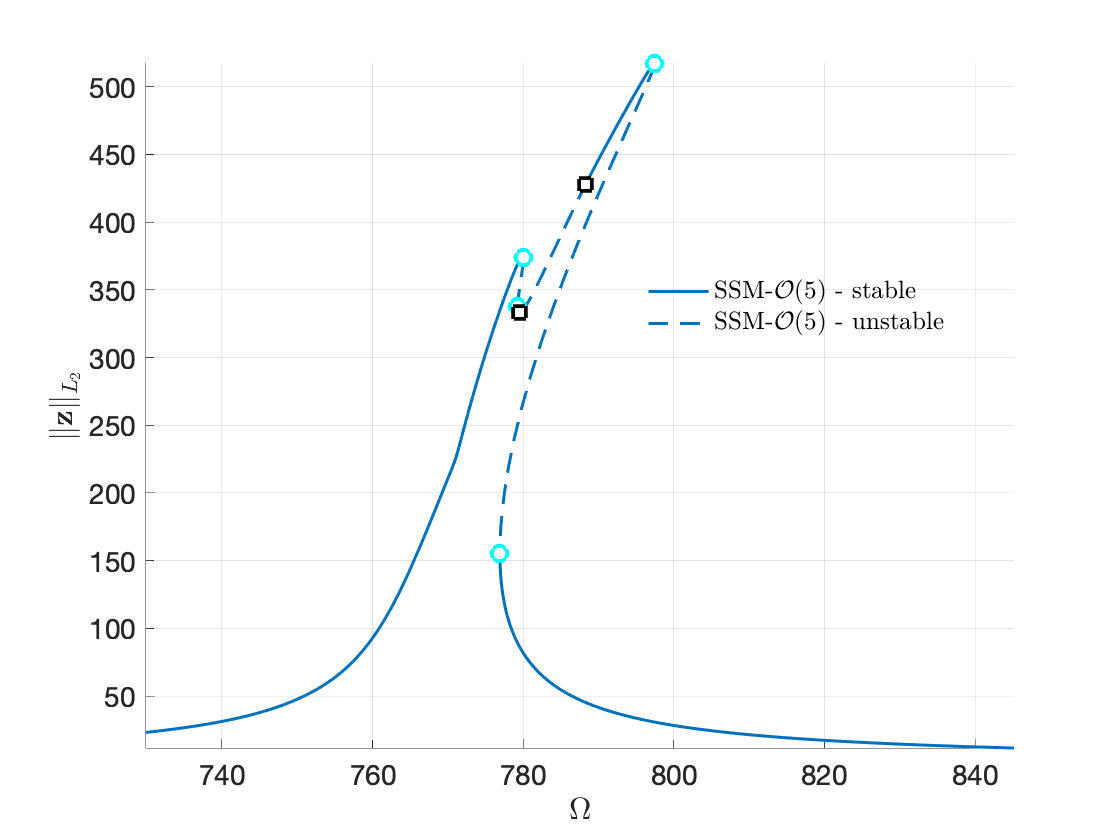

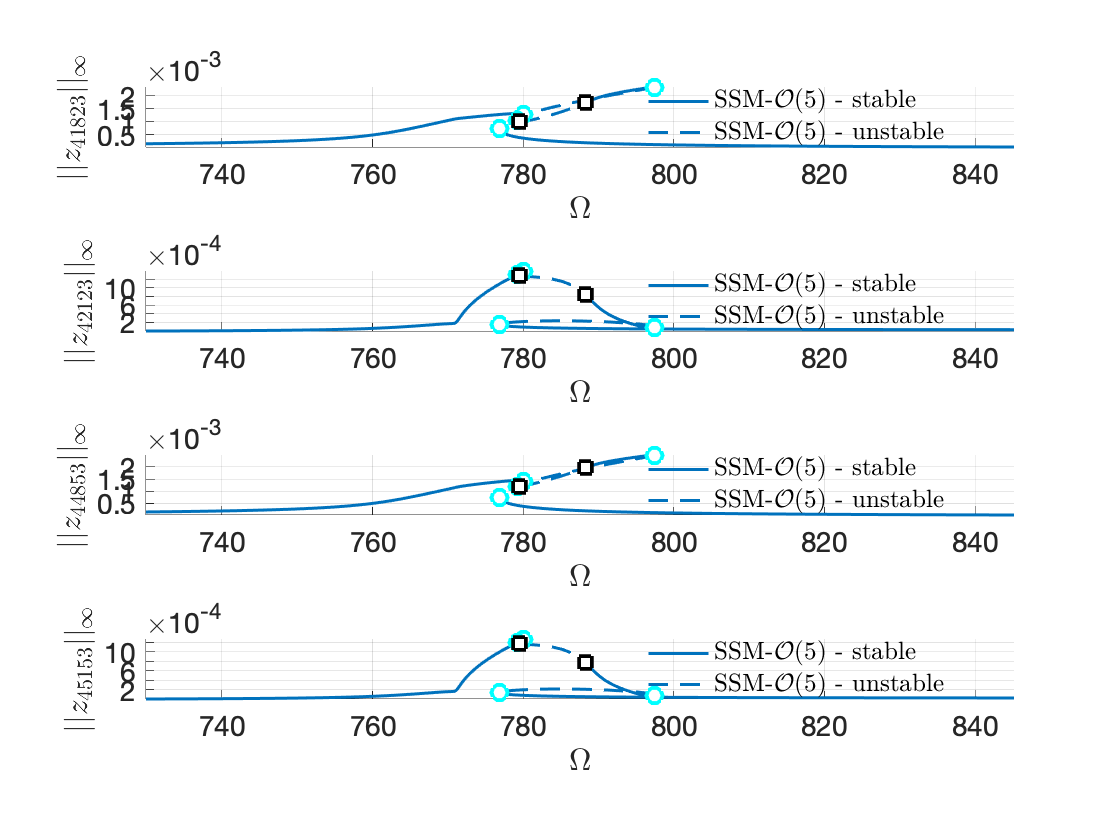

----------------------------------------------------------------
Delete parallel pool
----------------------------------------------------------------


S.deactivate_parallel();